# Example for using the `odericcati` function.

Copyright © 2021 Tamas Kis

Consider the state space system

            
$$\mathbf{A}=\left\lbrack \begin{array}{cc}
1 & 1\\
2 & 1
\end{array}\right\rbrack$$


            
$$\mathbf{B}=\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$$


We want to design a finite-horizon LQR controller with the state, input, and cross-coupling weighting matrices

            
$$\mathbf{Q}=\left\lbrack \begin{array}{cc}
2 & 1\\
1 & 1
\end{array}\right\rbrack$$


            
$$\mathbf{R}=\left\lbrack 1\right\rbrack$$


            
$$\mathbf{S}=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right\rbrack$$


Let's use the terminal condition (at time $t=T$)

            
$${\mathbf{P}}_T =\mathbf{P}\left(T\right)=\left\lbrack \begin{array}{cc}
1 & 1\\
1 & 1
\end{array}\right\rbrack$$


For the LQR controller, we need to find the $\mathbf{P}\left(t\right)\;\forall \;t\in \left\lbrack t_0 ,T\right\rbrack$. For this example, let $t_0 =0$ and $T=5$. Defining all matrices needed for the `odericcati` function (and noting that we don't have to define $\mathbf{S}$ since it is a zero matrix),

% state matrix
A = [1   1;
     2   1];

% input matrix
B = [1;
     1];

% state weighting matrix
Q = [2   1;
     1   1];

% input weighting matrix
R = 1;

% terminal condition
PT = [1   1;
      1   1];

Solving for $\mathbf{P}\left(t\right)$ using the `odericcati` function,

[t,P] = odericcati(A,B,Q,R,[],PT,[0,5]);

The solution of the corresponding continuous-time *algebraic* Riccati equation, ${\mathbf{P}}_{\infty \;}$, can be found using MATLAB's `icare` function.

Pinf = icare(A,B,Q,R);

Calculating ${\left\|\mathbf{P}\left(t\right)\right\|}_{\mathrm{F}}$ over the interval $t\in \left\lbrack 0,5\right\rbrack$,

P_norm = zeros(size(t));
for i = 1:length(t)
    P_norm(i) = norm(P(:,:,i),'fro');
end

Plotting the Frobenius norm of $\mathbf{P}\left(t\right)$ over the interval $t\in \left\lbrack 0,5\right\rbrack$ together with the Frobenius norm of ${\mathbf{P}}_{\infty \;}$,

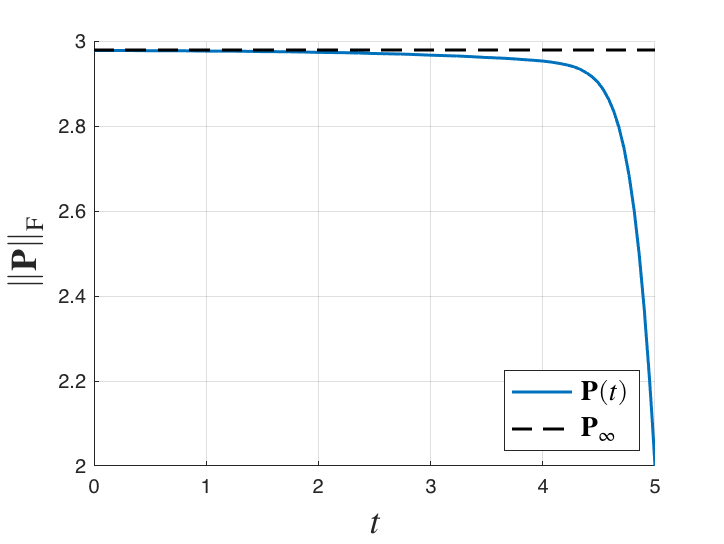

figure;
hold on;
plot(t,P_norm,'LineWidth',1.5);
plot(t,norm(Pinf,'fro')*ones(size(t)),'k--','LineWidth',1.5);
hold off;
grid on;
xlabel('$t$','interpreter','latex','fontsize',18);
ylabel('$\|\mathbf{P}\|_{\mathrm{F}}$','interpreter','latex','fontsize',18);
legend('$\mathbf{P}(t)$','$\mathbf{P}_{\infty}$','interpreter','latex','fontsize',14,'location','southeast');
hold off;